# Deep Learning Bearing Fault diagnosis

clc; close all; clear all;

class_num = 8;          % 4, 8, 10
mdl_struct = "CNN_1D"   % CNN_1D, CNN_2D, CNN_LSTM


## Step 1: Data Load

% For 1D - CNN , CNN - LSTM
[data, label] = data_load("8Class_custom");

% For 2D - CNN
% imds =imageDatastore('../Fault Dignosis/data/pre_data/CWRU_image_data', 'IncludeSubfolders',true,'LabelSource', 'foldernames');


## Step 2: Data Split

7:3

% For 1D - CNN , CNN - LSTM
[train,train_label,test,test_label] = data_split(data,label);

% For 2D - CNN
% [train,test] = splitEachLabel(imds,0.7,'randomized');

## Step 3: Select DeepLearning Layer

layer = layer(mdl_struct,class_num);   % Choose layer and the number of output
analyzeNetwork(layer)         % Analyze Deeplearning layers

## Step 4: Hyperparameter setting

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ExecutionEnvironment', 'gpu' ...
    );

## Step 5: Training

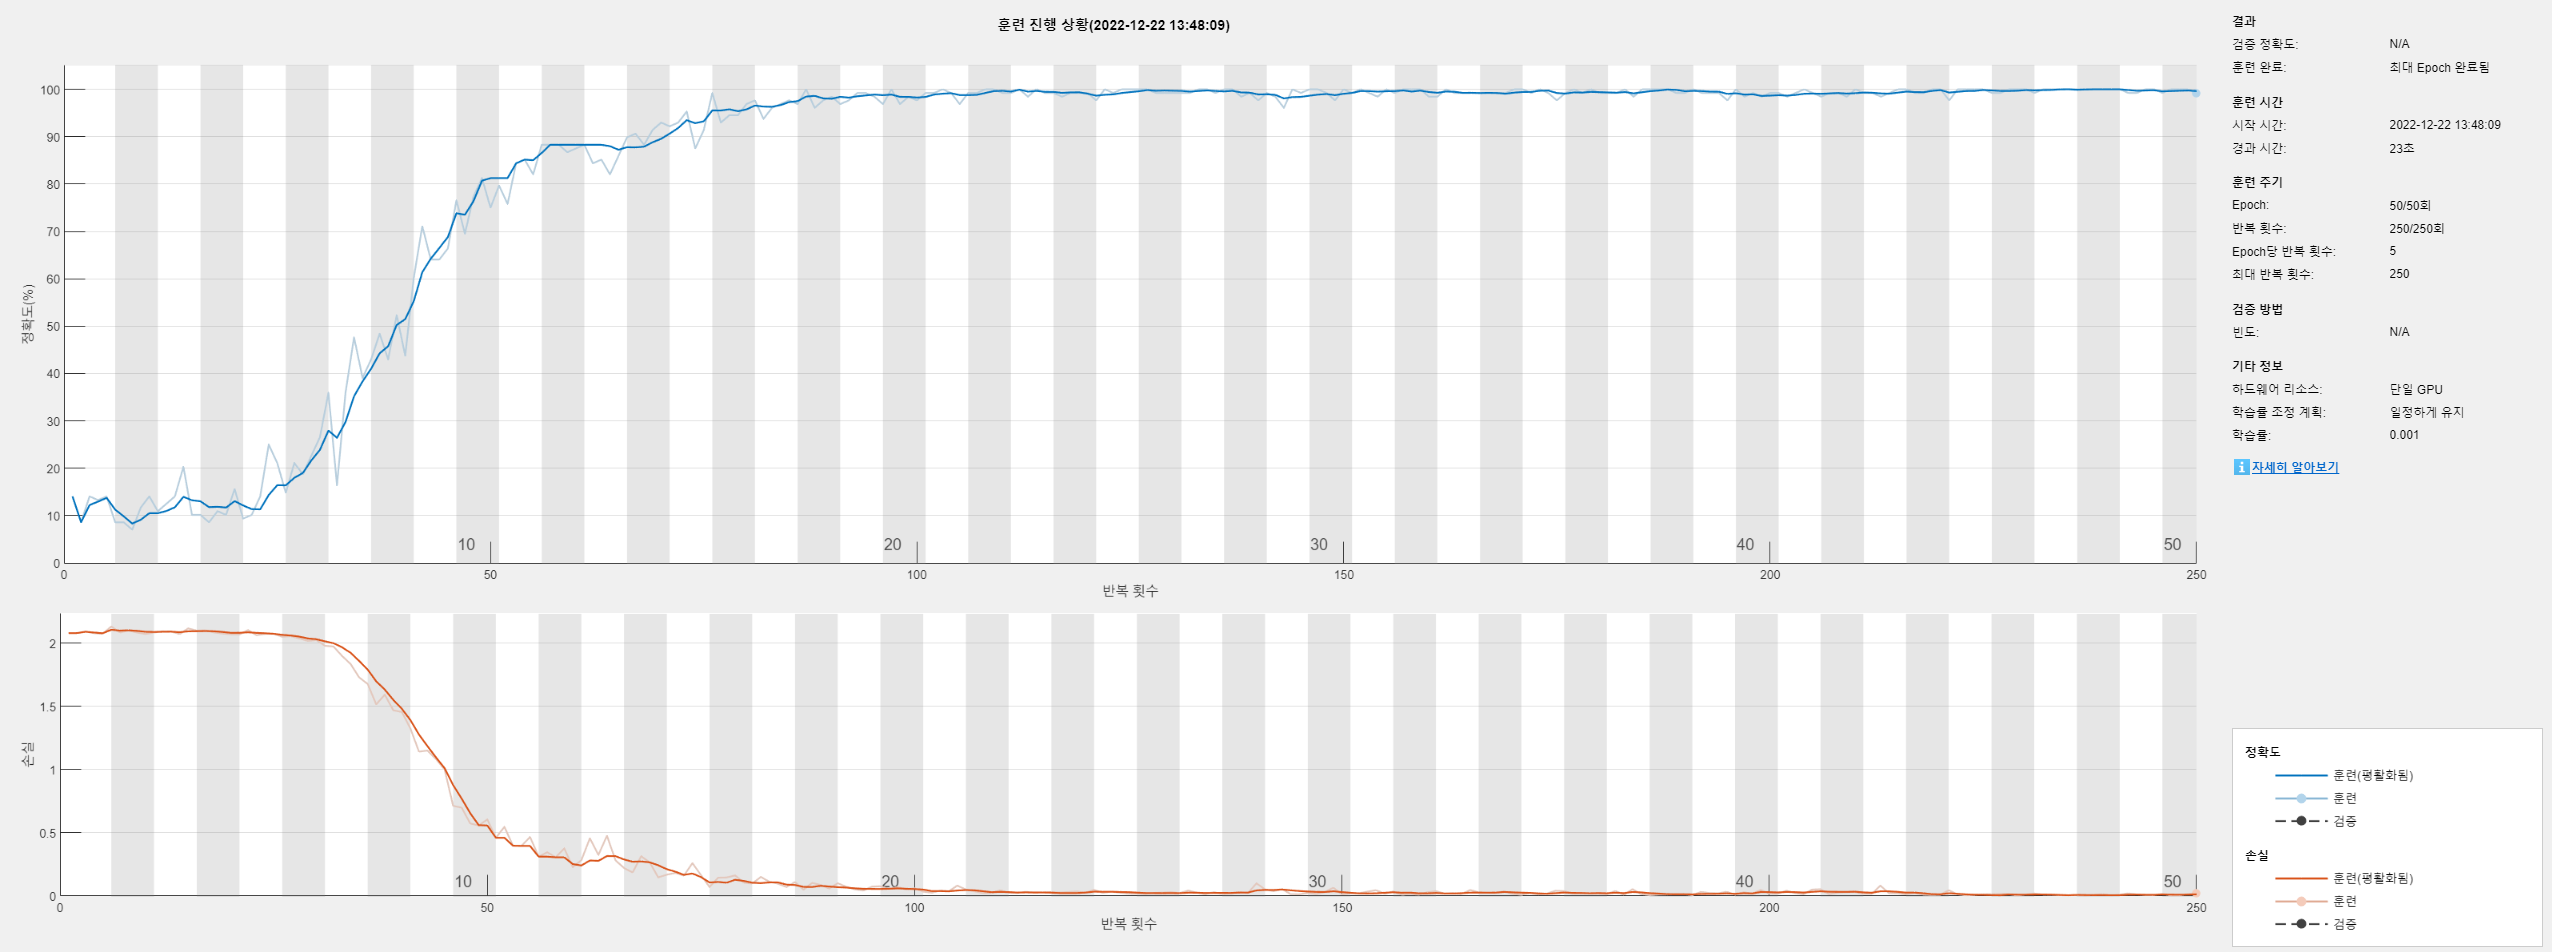

model =   SeriesNetwork - 속성 있음:

         Layers: [23×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


% For 1D - CNN , CNN - LSTM
model = trainNetwork(train,train_label,layer,options)


% For 2D - CNN
% model = trainNetwork(train,layer,options)

## Step 6: Result Analysis

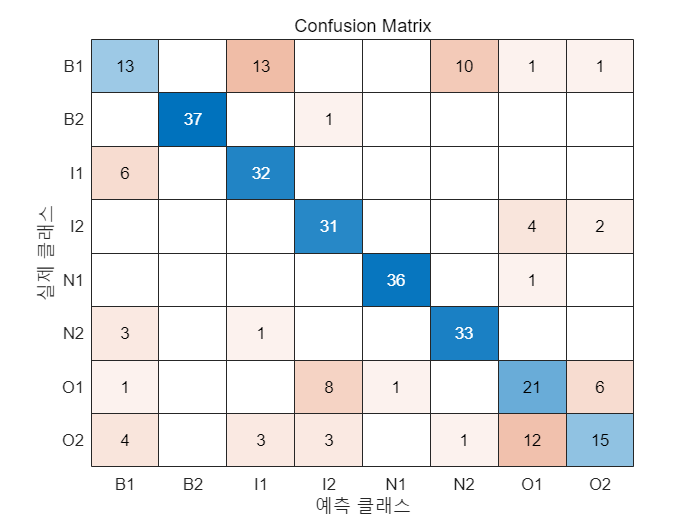

% For 1D - CNN , CNN - LSTM 
YPredicted = classify(model,test);
fig = figure;
cm = confusionchart(test_label,YPredicted);
cm.Title = 'Confusion Matrix';

[table1, table2]=Evaluation_ConfMat(cm)

table1 = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy          0.72667     
    Precision         0.71774     
    Recall            0.72786     
    F1_score           0.7152     


table2 = 8×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

         0.48148               0.34211                   0.4      
               1               0.97368               0.98667      
         0.65306               0.84211               0.73563      
         0.72093               0.83784                 0.775      
         0.97297               0.97297               0.97297      
            0.75               0.89189               0.81481      
         0.53846               0.56757               0.55263      
           0.625               0.39474               0.48387      



% For 2D - CNN
% YPredicted = classify(model,test);
% fig = figure;
% cm = confusionchart(test.Labels,YPredicted);
% cm.Title = 'Confusion Matrix';
% [table1, table2]=Evaluation_ConfMat(cm)